% Set random seed based on the current time to ensure different results for each run
rng('shuffle');  

% Parameters
format long

% Observed and estimated traffic flow data
observedQ = [300, 420, 480, 540, 600];  % Observed travel times (in seconds)
sigma = 30;                             % Standard deviation of observed data (in seconds)
lambda = 0.05;                          % Regularization parameter

% Additional Parameters for the Bangalore Metro Traffic Recovery
arrivalTimes = [300, 420, 240, 360, 480];  % in seconds
departureTimes = [0, 300, 420, 240, 360];  % in seconds
idealTimes = [240, 300, 360, 420, 480];    % in seconds
actualTimes = [300, 420, 480, 540, 600];   % in seconds
distances = [2000, 2000, 2500, 3000, 1500]; % in meters
speeds = [8.33, 8.33, 6.94, 5.56, 11.11];  % in m/s
gamma = 0.01;                              % Emission factor in kg CO₂ per meter
alpha = 0.05;                              % Fuel coefficient per distance
beta = 0.01;                               % Fuel coefficient per time
delta = 0.02;                              % Emission penalty factor
theta = 0.03;                              % Fuel consumption penalty factor

% Congestion-related parameters (Same as DE)
recklessDriving = [1, 0, 1, 0, 0];  % Binary array representing reckless driving instances
railroadDelays = [0, 1, 0, 0, 1];   % Binary array representing railroad delays
signalDelays = [1, 0, 1, 0, 0];     % Binary array representing signal delays
emissions = [0.5, 0.4, 0.3, 0.6, 0.7]; % Emissions for each trip
fuelConsumption = [0.1, 0.15, 0.2, 0.12, 0.1]; % Fuel consumption per trip

% GA parameters
numParticles = 5;                       % Number of traffic segments (dimensionality)
positionRange = [0, 1];                 % Position range for optimization
populationSize = 50;                    % Population size for GA
maxGenerations = 100;                   % Max generations for GA
tolerance = 1e-6;                       % Tolerance for minimal fitness change
maxStallGenerations = 10;               % Max generations to tolerate minimal change
stallCounter = 0;                       % Counter for stall generations

% Initialize population and fitness tracking
population = positionRange(1) + (positionRange(2) - positionRange(1)) * rand(populationSize, numParticles);
fitnessFunction = @(Q) objectiveFunction(Q', observedQ, sigma, lambda, ...
    recklessDriving, railroadDelays, signalDelays, emissions, fuelConsumption, ...
    alpha, beta, gamma, delta, theta, actualTimes, speeds, distances);
bestFitnessValues = zeros(1, maxGenerations);

% Start the timer
tic;

% GA Optimization Loop
disp('Running GA:');

Running GA:


for gen = 1:maxGenerations
    % Evaluate fitness of each individual in the population
    fitnessValues = arrayfun(@(idx) fitnessFunction(population(idx, :)), 1:populationSize);
    
    % Store best fitness of the current generation
    [bestFitness, bestIndex] = min(fitnessValues);
    bestFitnessValues(gen) = bestFitness;
    
    % Display current generation and best fitness
    disp(['Generation ', num2str(gen), ', Best Fitness: ', num2str(bestFitness)]);
    
    % Check for early stopping
    if gen > 1 && abs(bestFitnessValues(gen) - bestFitnessValues(gen-1)) < tolerance
        stallCounter = stallCounter + 1;
        if stallCounter >= maxStallGenerations
            disp(['Terminating early at generation ', num2str(gen), ' due to minimal change in fitness.']);
            break;
        end
    else
        stallCounter = 0;
    end
    
    % Selection, crossover, and mutation 
    parents = population(randperm(populationSize, floor(populationSize / 2)), :);
    offspring = crossoverAndMutation(parents, positionRange, numParticles);
    population = [parents; offspring];
end

Generation 1, Best Fitness: 0.26468
Generation 2, Best Fitness: 0.25554
Generation 3, Best Fitness: 0.26358
Generation 4, Best Fitness: 0.26358
Generation 5, Best Fitness: 0.26358
Generation 6, Best Fitness: 0.27213
Generation 7, Best Fitness: 0.29266
Generation 8, Best Fitness: 0.29266
Generation 9, Best Fitness: 0.29266
Generation 10, Best Fitness: 0.29266
Generation 11, Best Fitness: 0.27941
Generation 12, Best Fitness: 0.27666
Generation 13, Best Fitness: 0.27666
Generation 14, Best Fitness: 0.25766
Generation 15, Best Fitness: 0.27009
Generation 16, Best Fitness: 0.27941
Generation 17, Best Fitness: 0.2817
Generation 18, Best Fitness: 0.2817
Generation 19, Best Fitness: 0.2817
Generation 20, Best Fitness: 0.2817
Generation 21, Best Fitness: 0.2817
Generation 22, Best Fitness: 0.2835
Generation 23, Best Fitness: 0.28141
Generation 24, Best Fitness: 0.27219
Generation 25, Best Fitness: 0.27254
Generation 26, Best Fitness: 0.27847
Generation 27, Best Fitness: 0.27429
Generation 28, B


% Stop the timer and display runtime
totalTime = toc;
disp(['Total Runtime: ', num2str(totalTime), ' seconds']);

Total Runtime: 0.072591 seconds


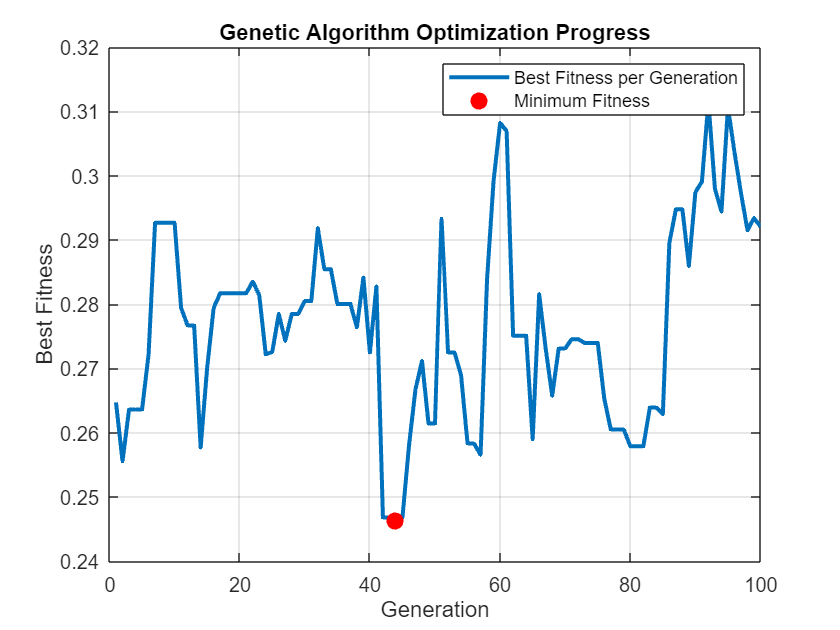


% Plot the best fitness value across generations
figure;
plot(1:gen, bestFitnessValues(1:gen), 'LineWidth', 2);
hold on;

% Find the minimum fitness value and its index
[minFitness, minIndex] = min(bestFitnessValues(1:gen));

% Highlight the minimum with a red dot
plot(minIndex, minFitness, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Add labels and title
xlabel('Generation');
ylabel('Best Fitness');
title('Genetic Algorithm Optimization Progress');
grid on;

% Display the minimum value in the legend
legend('Best Fitness per Generation', 'Minimum Fitness');
hold off;


% Output the best solution after the final generation
bestSolutionGA = population(bestIndex, :);
disp(['GA Best Solution: ', num2str(bestSolutionGA)]);

GA Best Solution: 0.90221     0.50481     0.70038    0.060628     0.36565


disp(['GA Best Fitness: ', num2str(minFitness)]);

GA Best Fitness: 0.24633



% Objective function for GA (similar to the PSO objective function)

function F = objectiveFunction(Q, observedQ, sigma, lambda, RD, RC, S, E, Fcons, alpha, beta, gamma, delta, theta, actualTimes, speeds, distances)
    % Compute penalties
    discrepancyTerm = 0;
    for i = 1:length(Q)
        % Calculate discrepancy based on delta(t_i) - (t_i * v_i) / s_i
        discrepancyTerm = discrepancyTerm + (delta - ((actualTimes(i) * speeds(i)) / distances(i)) - Q(i))^2;
    end
    discrepancyTerm = discrepancyTerm / sigma^2;
    
    % Regularization term
    regularizationTerm = lambda * norm(Q, 2)^2;
    
    % Penalties
    recklessDrivingPenalty = alpha * sum(RD);
    railroadDelayPenalty = beta * sum(RC);
    signalDelayPenalty = gamma * sum(S);
    emissionPenalty = delta * sum(E);
    fuelPenalty = theta * sum(Fcons);
    
    % Combine terms into the final objective function
    F = 1 * (discrepancyTerm + regularizationTerm + recklessDrivingPenalty ...
        + railroadDelayPenalty + signalDelayPenalty + emissionPenalty + fuelPenalty);
end

% Crossover and Mutation
function offspring = crossoverAndMutation(parents, positionRange, numParticles)
    numParents = size(parents, 1);
    numOffspring = numParents;
    offspring = zeros(numOffspring, numParticles);
    for i = 1:numOffspring
        % Randomly select parents
        parent1 = parents(randi(numParents), :);
        parent2 = parents(randi(numParents), :);
        
        % Uniform crossover
        mask = rand(1, numParticles) > 0.5;
        offspring(i, :) = mask .* parent1 + (~mask) .* parent2;
        
        % Mutation
        mutationProb = 0.1;
        mutationIndices = rand(1, numParticles) < mutationProb;
        offspring(i, mutationIndices) = positionRange(1) + ...
            (positionRange(2) - positionRange(1)) * rand(1, sum(mutationIndices));
    end
end
